## Import Menzies Data

clear;
data = readtable("data.xlsx")

data = 8760×25 table
    meter_serial            meter_desc                   tstamp              date            day           time          tou         week_number            impwh             difference_imp_kwh     ptot      stot     expwh    difference_exp_kwh    pftot      md       qtot      epoch_timestamp        interval_start       waste    meter_id    tou_id    season_profile_id    season_class_id    tariff_id
    ____________    __________________________    ____________________    ___________


%Remove data with no information  
data = removevars(data, ["meter_serial", "tstamp","meter_desc", "expwh","difference_exp_kwh","interval_start", "waste", "meter_id", "tariff_id","tou"]);

data.impwh = erase(data.impwh,',');
data.epoch_timestamp = erase(data.epoch_timestamp, ',');

data.impwh = str2double(data.impwh);
data.impwh = data.impwh./1000;

initalVal = data.impwh(1);
data.impwh = data.impwh - initalVal;

data.day = day(data.date, "iso-dayofweek");
data.date = day(data.date, "dayofyear");

% tou make hot one var because of nominal value
% same shit for day of week
% 


%data.tstamp = hour(data.tstamp);
%data.impwh is a running total. The total starts at like 10 million kWh, 
% Should I minus the first value from all of them to get just the
%running total of the year I have data for? Or is that messing with data
%and shit. 
data.epoch_timestamp = str2double(data.epoch_timestamp);
%Still need to sort out
%        days of the week
%        null entries
%        Tariff_id entry


Cleaning data

- MCAR (Missing completely at random): These are values that are randomly missing and do not depend on any other values.

- MAR (Missing at random): These values are dependent on some additional features.

- MNAR (Missing not at random): There is a reason behind why these values are missing.

missingElements = ismissing(data, {string(missing),NaN});
rowsWithMissing = any(missingElements, 2);

missingValuesTable = data(rowsWithMissing,:);

data = rmmissing(data)

data = 8754×15 table
    date    day      time      week_number    impwh     difference_imp_kwh     ptot      stot     pftot      md       qtot     epoch_timestamp    tou_id    season_profile_id    season_class_id
    ____    ___    ________    ___________    ______    __________________    ______    ______    _____    ______    ______    _______________    ______    _________________    _______________

     1       6            0         1              0          96.855          96.8


summary(data)

Variables:

    date: 8754×1 double

        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8754×1 double

        Values:

            Min          1    
            Median       4    
            Max          7    

    time: 8754×1 double

        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    week_number: 8754×1 double

        Values:

            Min           1   
            Median       27   
            Max          53   

    impwh: 8754×1 double

        Values:

            Min                0
            Median    7.5239e+05
            Max         1.46e+06

    difference_imp_kwh: 8754×1 double

        Values:

            Min             0 
            Median     160.79 
            Max        304.46 

    ptot: 8754×1 double

 

Adding in futValues

futPtot = array2table(data.ptot(25:end),"VariableNames","futPtot");
data = horzcat(data(1:end-24,:), futPtot)

data = 8730×16 table
    date    day      time      week_number    impwh     difference_imp_kwh     ptot      stot     pftot      md       qtot     epoch_timestamp    tou_id    season_profile_id    season_class_id    futPtot
    ____    ___    ________    ___________    ______    __________________    ______    ______    _____    ______    ______    _______________    ______    _________________    _______________    _______

     1       6            

[`N`](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_9405678c-6c76-491a-83e4-b928ee0b5cee) `= normalize(`[`A`](https://www.mathworks.com/help/matlab/ref/double.normalize.html#d124e1045357)`)` returns the vectorwise [*z*-score](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_e6886c44-2923-4074-844a-f3e1a447359d) of the data in `A` with center 0 and standard deviation 1.

- If `A` is a table or timetable, then `normalize` operates on each variable of `A` separately.

data = normalize(data);


my normal 

Xhat = (X-Xmin)/(Xmax-Xmix)

summary(data)

Variables:

    date: 8730×1 double

        Values:

            Min          -1.7264
            Median    -0.0042441
            Max           1.7275

    day: 8730×1 double

        Values:

            Min         -1.4995
            Median    0.0010313
            Max          1.5016

    time: 8730×1 double

        Values:

            Min          -1.6614
            Median    4.9647e-05
            Max           1.6615

    week_number: 8730×1 double

        Values:

            Min         -1.7548
            Median    -0.023252
            Max          1.7083

    impwh: 8730×1 double

        Values:

            Min        -1.7371
            Median    0.016549
            Max         1.6646

    difference_imp_kwh: 8730×1 double

        Values:

            Min        -2.8736
            Median    -0.10262
            Max         2.3707

    ptot: 8730

Looking for outliers

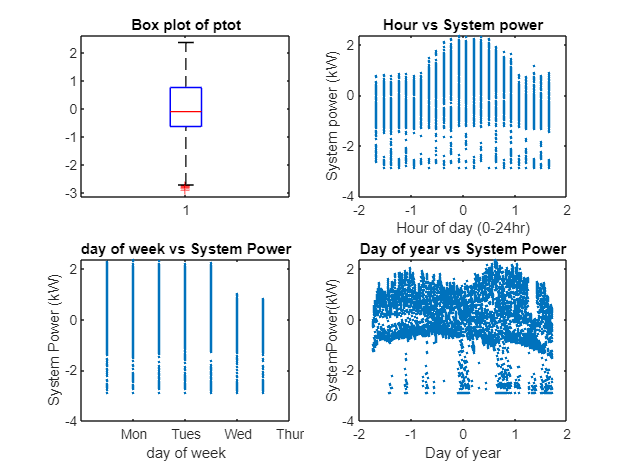


subplot(2,2,1)
boxplot(data.ptot)
title("Box plot of ptot")
subplot(2,2,2)
gscatter(data.time,data.ptot)
title("Hour vs System power")
ylabel("System power (kW)")
xlabel("Hour of day (0-24hr)")
subplot(2,2,3)
gscatter(data.day, data.ptot)
title("day of week vs System Power")
ylabel("System Power (kW)")
xlabel("day of week")
xticklabels(["","Mon","Tues", "Wed", "Thur", "Fri", "Sat", "Sun"])
subplot(2,2,4)
gscatter(data.date, data.ptot)
title("Day of year vs System Power") %average per day data and show one point per day (or show peak per day)
ylabel("SystemPower(kW)")
xlabel("Day of year")

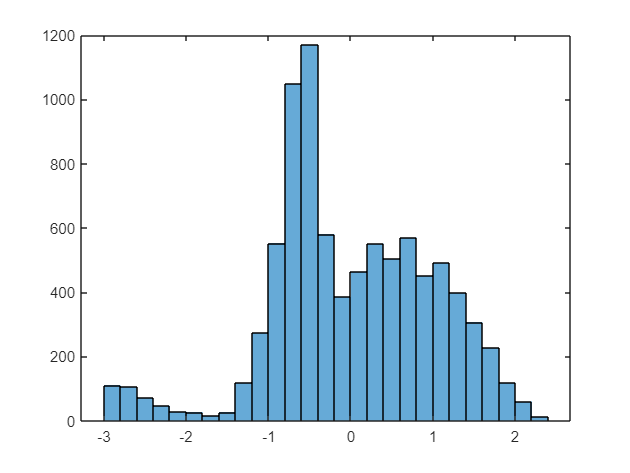


figure
histogram(data.ptot) %bimodal, intersetting - sepertate working hours vs off hours to look at each peak


% figure
% 
% X = [data.date,data.tstamp,data.day,data.ptot];
% varNames = {'Day of Year'; 'Time of Day'; 'Day of Week'; 'System True Power'};
% 
% gplotmatrix(X);
% text([.08 .24 .43 .66 ], repmat(-.1,1,4), varNames, 'FontSize',8);
% text(repmat(-.12,1,4), [.86 .62 .41 .25 ], varNames, 'FontSize',8, 'Rotation',90);

### Dimensionality Reduction

%Try PCA

PCA

pcaArray = data(:,1:end-1);
pcaArray = table2array(pcaArray);

[pcs,scrs,~,~,pctExp] = pca(pcaArray);

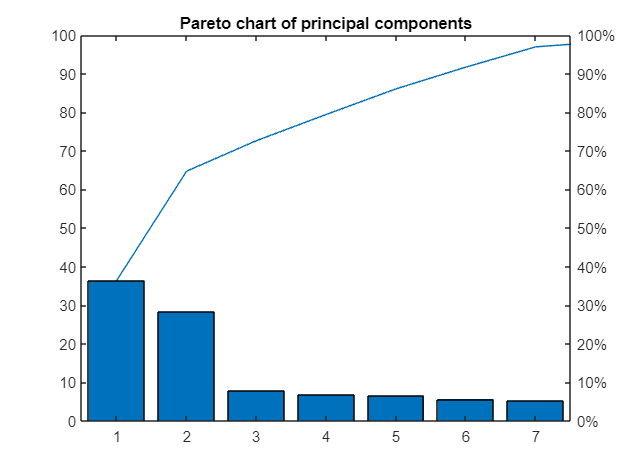

figure
pareto(pctExp)
title("Pareto chart of principal components")

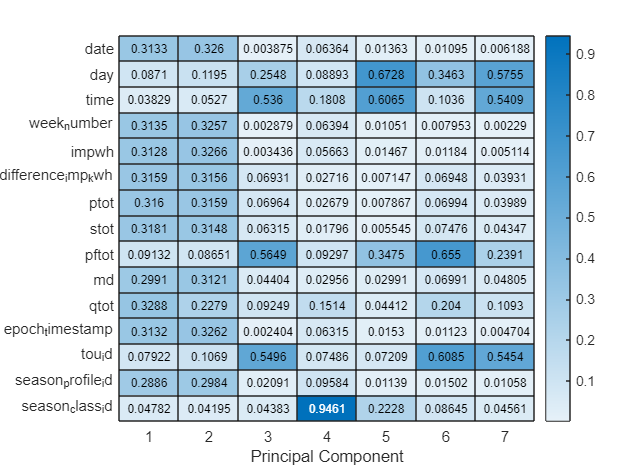


varnames= data.Properties.VariableNames;
 heatmap(abs(pcs(:,1:7)),...
     "YDisplayLabels",varnames(1:end-1));
 xlabel("Principal Component")


 dataReduced= scrs(:,1:9)

dataReduced =     0.5287   -4.5513    1.1069    0.4328   -0.2675    0.4446    1.0405    0.5124    0.2249
    0.5408   -4.5371    1.0301    0.4069   -0.1797    0.4275    0.9629    0.5113    0.2242
    0.5551   -4.5211    0.9528    0.3818   -0.0922    0.4092    0.8857    0.5084    0.2285
    0.5499   -4.5227    0.8751    0.3544   -0.0042    0.3982    0.8055    0.5094    0.2230
    0.5741   -4.4962    0.8015    0.3272    0.0837    0.3788    0.7301    0.5129    0.2029
    0.5795   -4.4854    0.7276    0.2964    0.1733    0.3670    0.6478    0.5209    0.1911
    2.0907   -3.0943    0.6478    0.3937    0.1831   -0.2787    0.8291    0.4053    0.4221
    2.2919   -2.8884    0.5968    0.3562    0.2839   -0.3439    0.7386    0.4252    0.5364
    2.2808   -2.9008    0.5194    0.3340    0.3654   -0.3554    0.6789    0.4256    0.4202
    2.3134   -2.8646    0.4529    0.3038    0.4580   -0.3697    0.5980    0.4316    0.4115


Sequential Feature Analysis

%ferror = @(XTrain,yTrain,XTest,yTest) nnz(yTest ~= predict(fitctree(XTrain,yTrain),XTest));

%toKeep = sequentialfs(ferror,data{:,1:end-1},data.futPtot)


### Anomaly Detection

%Can use statistical methods to find outliers

%Can try use some ML ting


MORE EDA

stratification (Strata)

- seperate data into strata

- ptot by day/month/season

- boxplots slap

#### Fucken around and trying some shit

[https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html) Useful shit for 

predicting future timeseries values.

%removing casue fitrsvm doesn't like them

% 
numObs = height(data);
percentSplit = 0.8;
idxTrain = 1:floor(percentSplit*numObs);                                
idxTest = floor(percentSplit*numObs)+1:numObs; 
dataTrain = data(idxTrain,:);
dataTest = data(idxTest,:);   

mdl = fitrsvm(dataTrain,"futPtot","Standardize",true, "KernelFunction","polynomial");

mdlLoss = loss(mdl, dataTest)

mdlLoss = 5.2732

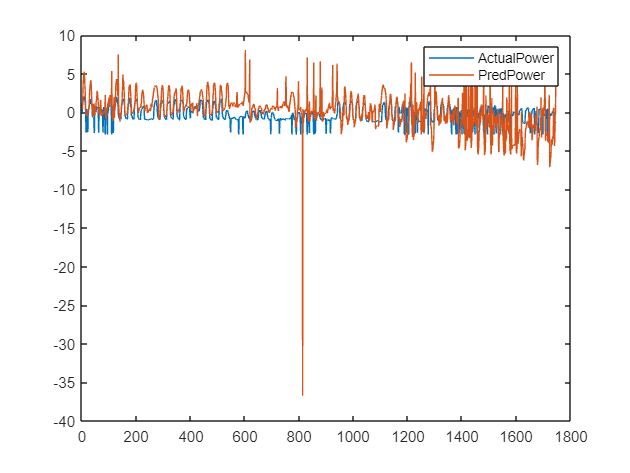

ptotPred = predict(mdl, dataTest);

figure
plot(dataTest.futPtot)
hold on
plot(ptotPred)
hold off
legend("ActualPower" , "PredPower")

%evaluateFit(dataTest.ptot, ptotPred, "SVM")

